clear all; close all; clc;
fdir = 'C:\Users\Tomo\Desktop\studies\2020-Spring\AAE440\MATLAB\outputs\HW11';
set(groot, 'defaulttextinterpreter','latex');  
set(groot, 'defaultAxesTickLabelInterpreter','latex');  
set(groot, 'defaultLegendInterpreter','latex');

## Extra for region 6

lgd =   Legend (particular sol, comparison sol 1, comparison sol 2) with properties:

         String: {'particular sol'  'comparison sol 1'  'comparison sol 2'}
       Location: 'southwest'
    Orientation: 'vertical'
       FontSize: 9
       Position: [0.1494 0.1349 0.2473 0.1148]
          Units: 'normalized'

  Show all properties


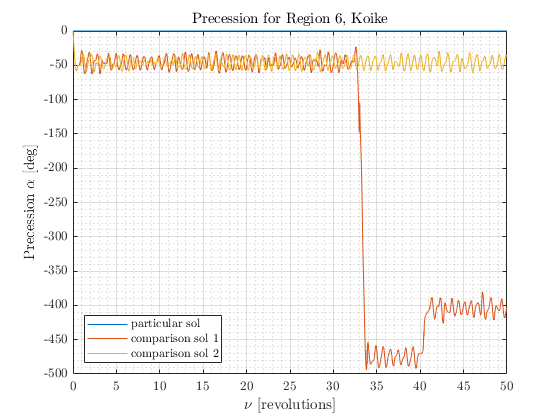

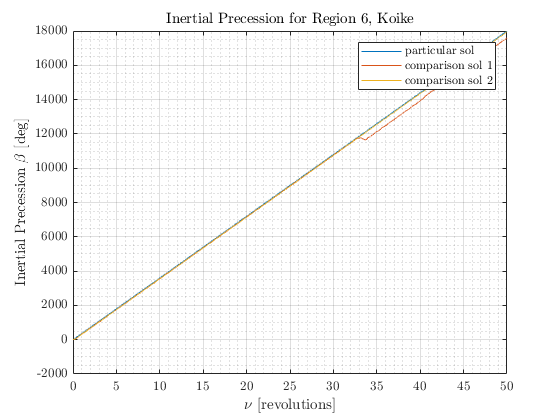

% Define Moment of Inertia [kg m2]
I_1 = 500;  I_2 = 425;  I_3 = 125;

% Shape factors
[K1, K2, K3] = K_from_orientation(I_1, I_2, I_3); % (ii)
N  = length(K1);

% K3 -K1 stability chart
f = 1; % scale factor
fig = figure(1);
    hold on
    plot(K3,K1,'r.',"MarkerSize",30)
    
    % Region 3 & 6 
    v1 = [0 0;f 0;f f;0 f;0 0;-f 0;-f -f;0 -f]; f1 = [1 2 3 4; 5 6 7 8];
    patch("Faces",f1,"Vertices",v1,"FaceColor",'blue','FaceAlpha',0.08);
    
    % Region 2 & 4
    v2 = [-f 0;-f f;0 0;0 0;0 -f;f -f]; f2 = [1 2 3; 4 5 6];
    patch("Faces",f2,"Vertices",v2,"FaceColor",'blue','FaceAlpha',0.08);
    
    % Separating Region 5 & 7
    x = 0.1459:0.001:f;
    roots = zeros(1,length(x));
    for i = 1:length(x)
        func = @(y) (1-x(i).*y+3.*y).^2 + 16.*x(i).*y;
        y0 = 0;
        roots(i) = fzero(func,y0);
    end
    plot(x,roots, 'k-')
    
    % Region 5 & 7
    v3 = [0 0;f 0;f -f]; f3 = [1 2 3];
    patch("Faces",f3,"Vertices",v3,"FaceColor",'blue','FaceAlpha',0.08);
    
    % Figure Properties
    title('$K_3$-$K_1$ Stability Chart , Koike')
    xlabel('$K_3$'); ylabel('$K_1$');
    lgd = legend('Vehicle Orientation','Unstable Region',"Location","northeastoutside");
    lgd.FontSize = 6;
    grid on; grid minor; axis equal; axis([-f f -f f]);
    
    % Region Numbers
    text(-0.2*f,0.6*f,'1',"FontSize",20,"Color",'k');
    text(-0.6*f,0.2*f,'2',"FontSize",20,"Color",'k');
    text(-0.4*f,-0.4*f,'3',"FontSize",20,"Color",'k');
    text(0.2*f,-0.6*f,'4',"FontSize",20,"Color",'k');
    text(0.6*f,-0.2*f,'5',"FontSize",20,"Color",'k');
    text(0.4*f,0.4*f,'6',"FontSize",20,"Color",'k');
    text(0.3,-0.05,'7',"FontSize",15,"Color",'k');
    str = sprintf("K3-K1_stability_chart_K1=%.2f_K2=%.2f_K3=%.2f.png",K1,K2,K3);
saveas(fig,fullfile(fdir,str));

close all;

% Revolutions
v = 50; revN = length(v);
gamma0 = 0;
for k = 1:revN
    
    rev = 0:0.003:v(k);
    
    for j = 1:N % for different orientations
        
        for i = 1:3 % for different intial w
            w1 = [0 0.12 0.06]; w2 = [0 1 1]; w3 = [0 0.12 0.06];
            w0 = [w1(i) w2(i) w3(i)];                   % initial angular velocities
            e0 = [sind(gamma0/2) 0 0 cosd(gamma0/2)];   % initial euler parameters
            y  = [w0 e0 0];                             % Initial Conditions
            
            % Nutation and Precession History
            [rev, Nut, Prec] = Nut_Prec_UnsymmBody(rev,y,K1(j),K2(j),K3(j));
            
            % Plotting Precession Angle
            figure(j)
                hold on;
                if i == 1
                    plot(rev, Prec,'-','DisplayName','particular sol')
                else
                    plot(rev, Prec,'-','DisplayName',['comparison sol ',num2str(i-1)])
                end
                
            % Plotting Inertial Precession Angle
            sigma = 360*rev;
            beta = Prec+sigma;
            figure(j+N)
                hold on;
                if i == 1
                    plot(rev, beta,'-','DisplayName','particular sol')
                else
                    plot(rev, beta,'-','DisplayName',['comparison sol ',num2str(i-1)])
                end
        end
            fig1 = figure(j);
                xlabel('$\nu$ [revolutions]'); 
                ylabel('Precession $\alpha$ [deg]')
                grid on; grid minor; box on; lgd = legend;
                lgd.Location = 'southwest';
                str = sprintf('Precession for K1=%.2f K2=%.2f K3=%.2f',K1(j),K2(j),K3(j));
                str = sprintf('Precession for Region 6, Koike');
                title(str)
                str = sprintf('SIM_Alpha_K1=%.2f_K2=%.2f_K3=%.2f_rev%d_nut=%d.png',K1(j),K2(j),K3(j),v(k),gamma0);
            saveas(fig1, fullfile(fdir, str));

            fig2 = figure(j+N);
                xlabel('$\nu$ [revolutions]'); 
                ylabel('Inertial Precession $\beta$ [deg]')
                grid on; grid minor; box on; legend;
                str = sprintf('Inertial Precession for K1=%.2f K2=%.2f K3=%.2f',K1(j),K2(j),K3(j));
                str = sprintf('Inertial Precession for Region 6, Koike');
                title(str)
                str = sprintf('SIM_Beta_K1=%.2f_K2=%.2f_K3=%.2f_rev%d_nut=%d.png',K1(j),K2(j),K3(j),v(k),gamma0);
            saveas(fig2, fullfile(fdir, str));
    end
    close all;
end